## Introduction

In this scrip we try to visualize the residuals in parameter space.

## Loading residuals

residual_location='C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\数据模拟\P.S.v3\data\';
residual_filename='parameterselectionm,psi,zeta2021             11              6             21             24         42.184'

residual_filename = 'parameterselectionm,psi,zeta2021             11              6             21             24         42.184'

load([residual_location,residual_filename,'.mat']);

## Figuring

dot location

sampling_frequency=length(residual_compare);
location_m=zeros(sampling_frequency^3,1);
location_psi=zeros(sampling_frequency^3,1);
location_zeta=zeros(sampling_frequency^3,1);
residual_colour=zeros(sampling_frequency^3,1);
serial_number=1;

first way to visualize

for i_m=1:sampling_frequency

    for i_psi=1:sampling_frequency

        for i_zeta=1:sampling_frequency

            location_m(serial_number)=sample_m(i_m);

            location_psi(serial_number)=sample_psi(i_psi);

            location_zeta(serial_number)=sample_zeta(i_zeta);

            residual_colour(serial_number)=log(residual_compare(i_m,i_psi,i_zeta)/min(residual_compare,[],"all"));

            serial_number=serial_number+1;

        end

    end

end

another way to show 

for i_m=1:sampling_frequency
    for i_psi=1:sampling_frequency
        for i_zeta=1:sampling_frequency
            location_m(serial_number)=sample_m(i_m);
            location_psi(serial_number)=sample_psi(i_psi);
            location_zeta(serial_number)=sample_zeta(i_zeta);
            residual_colour(serial_number)=log(residual_compare(i_m,i_psi,i_zeta)/min(residual_compare,[],"all"));
            serial_number=serial_number+1;
        end
    end
end

figure

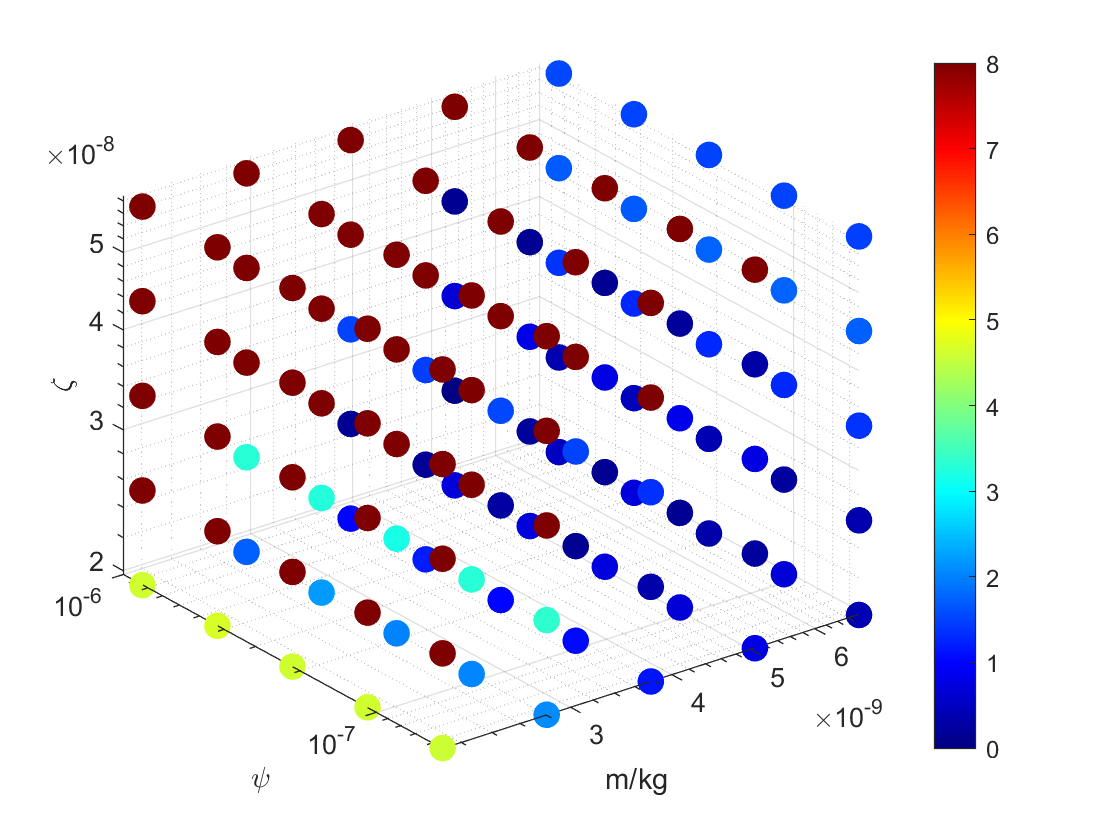

figure
scatter3(location_m,location_psi,location_zeta,100,residual_colour,'filled');
xlabel('m/kg');
ylabel('\psi');
zlabel('\zeta');
set(gca,'xscale','log');
set(gca,'yscale','log');
set(gca,'zscale','log');
colormap jet
caxis([0,8])
colorbar

bar figure

for i_zeta=1:sampling_frequency

    residual_compare2=residual_compare(:,:,i_zeta);

    figure

    bar3(residual_compare2)

end